Phenotype Table

phenotypes = readtable("NKI_1_phenotypic_data.csv");
obsolete_cols = get_obs_cols(phenotypes);

session1_phenotypes = phenotypes(strcmp(phenotypes.SESSION, 'Baseline'), :);
s1_obs = get_obs_cols(session1_phenotypes);

session2_phenotypes = phenotypes(strcmp(phenotypes.SESSION, 'Retest_1'), :);
s2_obs = get_obs_cols(session2_phenotypes);

obsolete_cols = obsolete_cols | s1_obs | s2_obs;
phenotypes(:, obsolete_cols) = [];
phenotypes = sortrows(phenotypes, "SUBID")

phenotypes = 48×12 table
      SUBID       AGE_AT_SCAN_1    HANDEDNESS    CURRENT_DIAGNOSIS    LIFETIME_DIAGNOSIS                              CURRENT_DX_1                                    CURRENT_DX_2                   LIFETIME_DX_1                  LIFETIME_DX_2          LIFETIME_DX_3    LIFETIME_DX_4    LIFETIME_DX_5
    __________    _____________    __________    _________________    __________________    ________________________________________________________________    _________________________    _____________________________    _________________________    _____________    _____________    

Network Statistics

network_stats = readtable("nki_network-master/o.csv");
network_stats = sortrows(network_stats, "subject_id");
network_stats.condition = phenotypes.LIFETIME_DIAGNOSIS(any(network_stats.subject_id == phenotypes.SUBID', 1))

network_stats = 40×7 table
    subject_id    session_number    density    avg_clst    avg_deg       r2        condition
    __________    ______________    _______    ________    _______    _________    _________

         21001          1           0.17452    0.63564     11.169     0.0043045     {'NO' } 
         21001          2           0.15865    0.63451     10.154      0.020847     {'NO' } 
         21002          2           0.17212    0.66603     11.015      0.084678     {'N/A'} 
         21002          1           0.16779    0.65398     10.738       0.10128     {'N/A'} 
         21006          2            0.1655     0.6904     10.758       0.22053     {'N/A'} 
         21006          1           0.17356    0.69285     11.108       0.38047    


net_stats_controls = network_stats(any(network_stats.subject_id == phenotypes.SUBID(strcmp(phenotypes.LIFETIME_DIAGNOSIS, 'NO'))', 2), :)

net_stats_controls = 24×7 table
    subject_id    session_number    density    avg_clst    avg_deg       r2        condition
    __________    ______________    _______    ________    _______    _________    _________

         21001          1           0.17452    0.63564     11.169     0.0043045     {'NO'}  
         21001          2           0.15865    0.63451     10.154      0.020847     {'NO'}  
    2.4754e+06          2           0.18155    0.68305     11.438       0.19066     {'NO'}  
    2.4754e+06          1           0.17548    0.67084     11.231       0.12163     {'NO'}  
    2.7993e+06          2           0.19643    0.68314     12.375       0.30548     {'NO'}  
    2.7993e+06          1           0.19279    0.66661     12.338       0.1444

net_stats_psychs = network_stats(any(network_stats.subject_id == phenotypes.SUBID(strcmp(phenotypes.LIFETIME_DIAGNOSIS, 'YES'))', 2), :)

net_stats_psychs = 8×7 table
    subject_id    session_number    density    avg_clst    avg_deg       r2       condition
    __________    ______________    _______    ________    _______    ________    _________

    1.7936e+06          1           0.15804    0.65621     10.273      0.16829     {'YES'} 
    1.7936e+06          2           0.14685    0.63532     9.5455     0.063819     {'YES'} 
    1.9611e+06          2           0.20089    0.69749     12.656      0.13855     {'YES'} 
    1.9611e+06          1           0.19712    0.68312     12.615     0.026359     {'YES'} 
    3.3133e+06          1           0.20839    0.68343     13.545      0.17568     {'YES'} 
    3.3133e+06          2           0.22098    0.69115     14.364     0.064783     {'YES

net_stats_unknowns = network_stats(any(network_stats.subject_id == phenotypes.SUBID(strcmp(phenotypes.LIFETIME_DIAGNOSIS, 'N/A'))', 2), :)

net_stats_unknowns = 8×7 table
    subject_id    session_number    density    avg_clst    avg_deg       r2       condition
    __________    ______________    _______    ________    _______    ________    _________

      21002             2           0.17212    0.66603     11.015     0.084678     {'N/A'} 
      21002             1           0.16779    0.65398     10.738      0.10128     {'N/A'} 
      21006             2            0.1655     0.6904     10.758      0.22053     {'N/A'} 
      21006             1           0.17356    0.69285     11.108      0.38047     {'N/A'} 
      21018             2           0.21478    0.69374     13.531     0.025814     {'N/A'} 
      21018             1           0.22222    0.70131     13.778     0.013094     {'N

Figures and p_vals

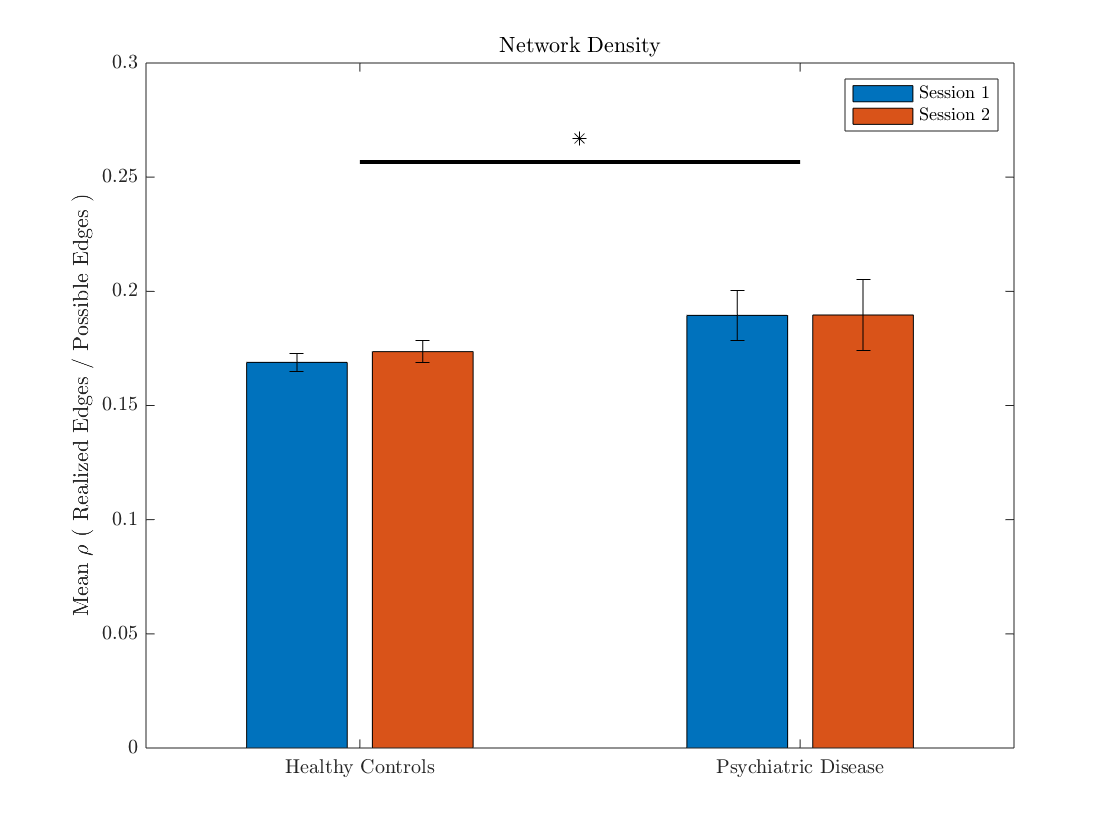

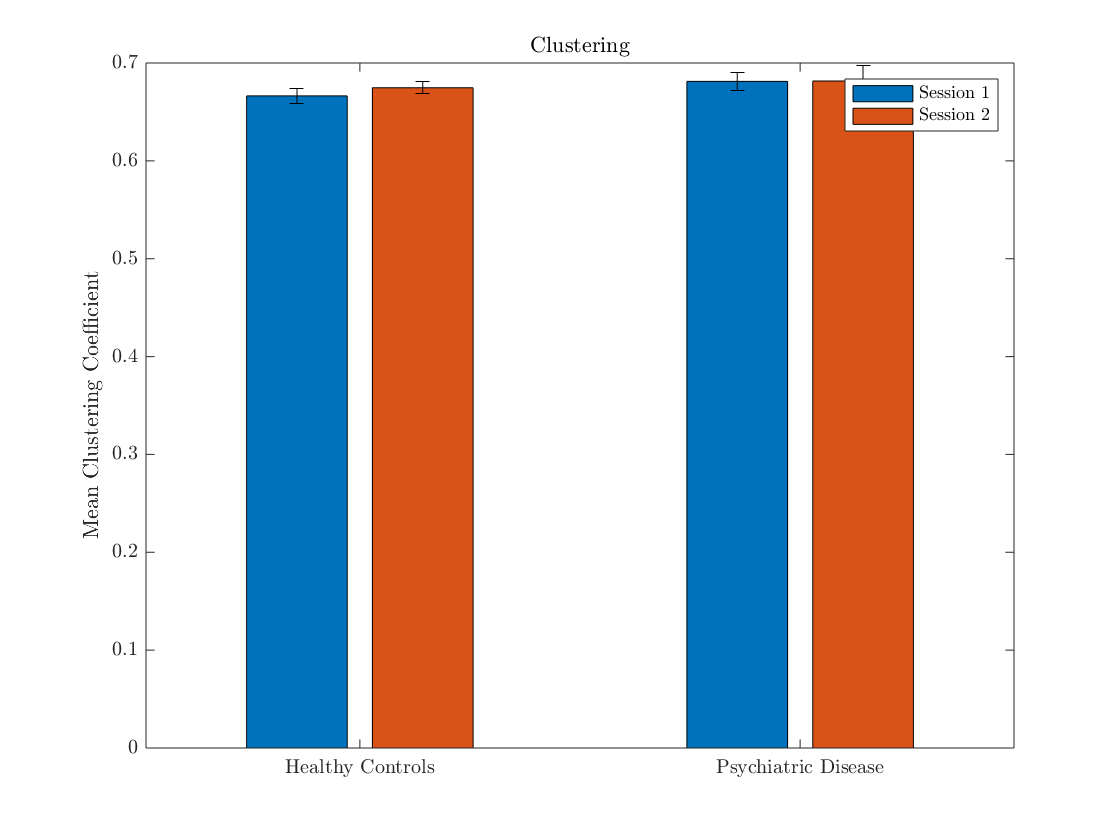

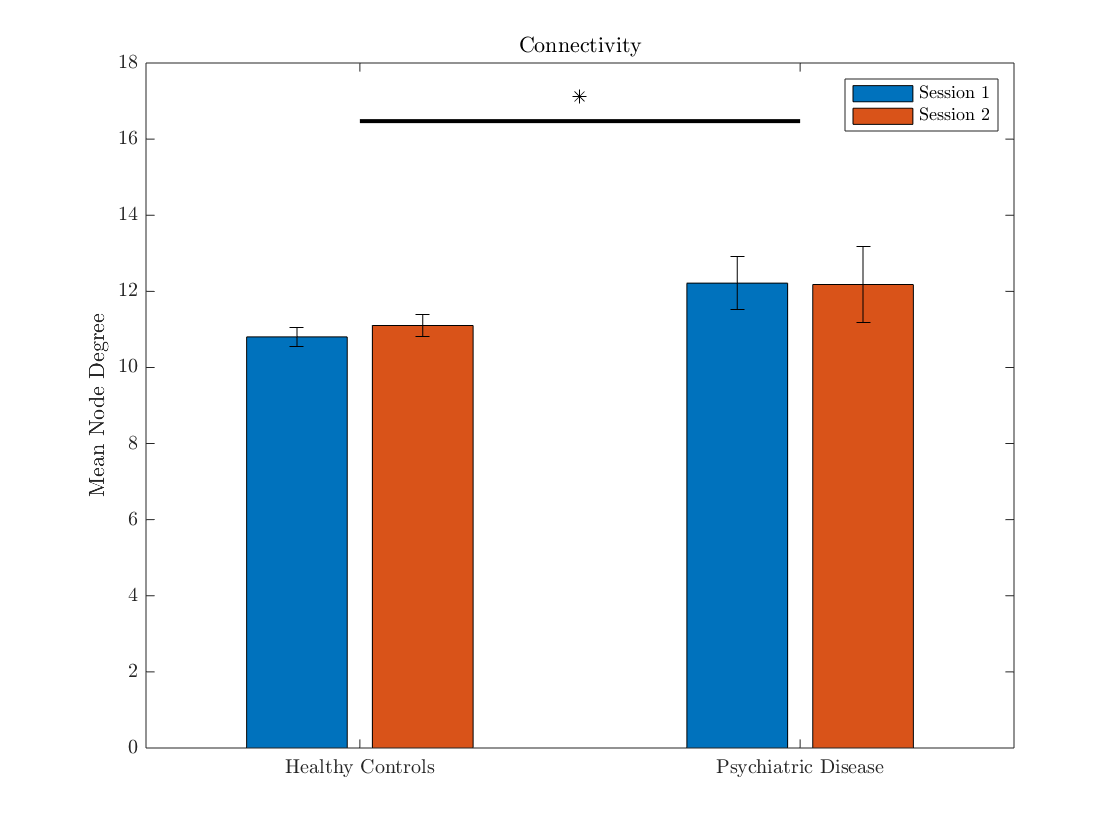

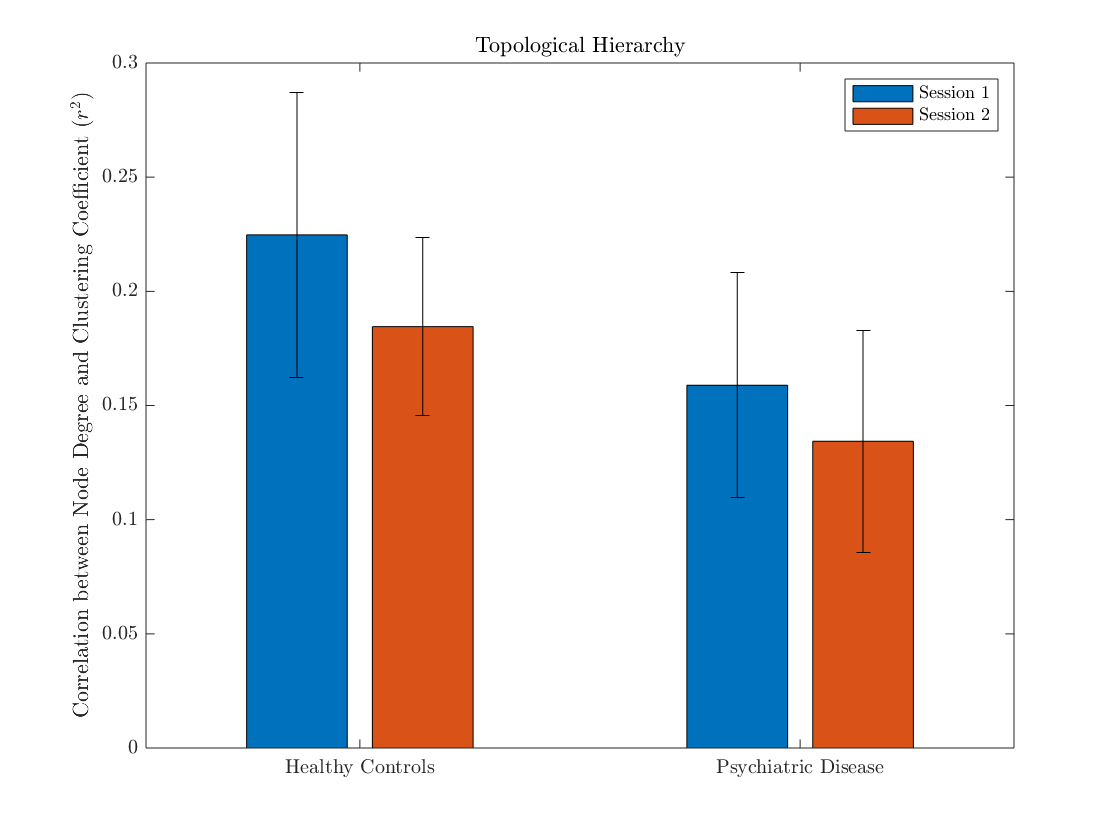

thresholds = ["90%"];
stats = ["density"; "avg_clst"; "avg_deg"; "r2"];
titles = ["Network Density", "Clustering", "Connectivity", "Topological Hierarchy"];
ylabels = ["Mean $\rho$ ( Realized Edges / Possible Edges )", "Mean Clustering Coefficient", "Mean Node Degree", "Correlation between Node Degree and Clustering Coefficient ($r^2$)"];

p_session = zeros([numel(stats), 1]);
p_condition = zeros([numel(stats), 1]);
for i = 1:numel(stats)
    p = plot_netstat(net_stats_controls, net_stats_psychs, stats(i), titles(i), ylabels(i));
    p_session(i) = p(1);
    p_condition(i) = p(2);
end


p_vals = table(stats, p_session, p_condition);
writetable(p_vals, "p_vals.csv", "Delimiter", ",");

Functions

function obs_cols = get_obs_cols(A)
    s = size(A);
    obs_cols = logical(zeros(1, s(2)));
    for col = 1:s(2)
        if isa(A{1, col}, 'cell')
        unique_entries = setdiff(A{:, col}, A{1,col});
        if numel(unique_entries) == 0
            obs_cols(1, col) = 1;
        end
    elseif isa(A{1, col}, "double")
        if all(A{:, col} == A{1, col})
            obs_cols(1, col) = 1;
        end
    end
    end
end

%plotting graphs without unknown category for simplicity
function p = plot_netstat(controls, psychs, stat, stat_title, stat_ylabel)
    %Segregate by session number
    control = controls.(stat);
    control_s1 = control(controls.session_number == 1);
    control_s2 = control(controls.session_number == 2);
    
    psych = psychs.(stat);
    psych_s1 = psych(psychs.session_number == 1);
    psych_s2 = psych(psychs.session_number == 2);
    
    %Caluclate means and SEMs
    control_means = [mean(control_s1), mean(control_s2)];
    psych_means = [mean(psych_s1), mean(psych_s2)];
    means = [control_means; psych_means];
    
    control_SEMs = [std(control_s1)/sqrt(numel(control_s1)), std(control_s2)/sqrt(numel(control_s2))];
    psych_SEMs = [std(psych_s1)/sqrt(numel(psych_s1)), std(psych_s2)/sqrt(numel(psych_s2))];
    SEMs = [control_SEMs; psych_SEMs];
    
    %Obtain p-vals controlling for multiple comparisons
    y = [control; psych];
    g_sesh = [controls.session_number; psychs.session_number];
    g_condition = [controls.condition; psychs.condition];
    p_vals = anovan(y, {g_sesh, g_condition}, "display", "off");
    p_sesh = p_vals(1);
    p_condition = p_vals(2);
    p = [p_sesh, p_condition];
    
    %Plot
    fig = figure();
    my_bars = bar(means);
    hold on
    xpos = [];
    for bar_idx = 1:numel(my_bars)
        xpos = [xpos; my_bars(bar_idx).XData + my_bars(bar_idx).XOffset];
    end
    xpos = xpos';
    errorbar(xpos, means, SEMs, "linestyle", "none", "Color", "k");
    set(gca, 'TickLabelInterpreter', 'latex');
    xticklabels(["Healthy Controls", "Psychiatric Disease"]);
    legend(["Session 1", "Session 2"], "Interpreter", "latex");
    title(stat_title, 'Interpreter', "latex");
    ylabel(stat_ylabel, 'Interpreter', "latex");
    
    SIG_THRESHOLD = 0.05;
    if p_sesh < SIG_THRESHOLD
        sigline_sesh([1, 2], xpos, means, SEMs);
        sigline_sesh([3, 4], xpos, means, SEMs);
    end
    if p_condition < SIG_THRESHOLD
        sigline_cond([1, 2], xpos, means, SEMs);
    end
    hold off
    saveas(fig, stat+"_bargraph", 'pdf');
    
end

function sigline_sesh(cols, xpos, means, SEMs)
    %MATLAB indexes matrices column by column --> take transpose to make it
    %index row by row
    xpos = xpos';
    means = means';
    SEMs = SEMs';
    y = means(cols) + SEMs(cols);
    
    line = plot(xpos(cols), 1.1 * max(y) * [1, 1], '-k', 'LineWidth', 2); %line
    sig_star = plot(mean(xpos(cols)), 1.15 * max(y), '*k'); %Significance * 
    
    %To omit from legend
    set(get(get(line,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    set(get(get(sig_star,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
end

function sigline_cond(groups, xpos, means, SEMs)
    %Identify center of each group and maximum mean and SEM
    xpos = mean(xpos, 2);
    means = max(means, [], 1);
    SEMs = max(SEMs, [], 1);
    y = means(groups) + SEMs(groups);
    
    line = plot(xpos(groups), 1.25 * max(y) * [1, 1], '-k', 'LineWidth', 2); %line
    sig_star = plot(mean(xpos(groups)), 1.3 * max(y), '*k'); %Significance * 
    
    %To omit from legend
    set(get(get(line,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    set(get(get(sig_star,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
end